clc;
clear;
load('example_data.mat');
load('SegmentationValues.mat');
fs = 1000;

%For visualization purposes and optimization of parameters
%Define spectrogram parameters
win_length_sec = 0.003;            %window length in seconds
hop_length_sec = win_length_sec/2; %hop length in seconds
nfft           = 2^12;             %FFT size
n_mels         = 128;              %number of mel frequency bands
fmin           = 0;                %minimum frequency in Hz
fmax           = fs/2;             %maximum frequency in Hz

[S,F,T] = melSpectrogram(Diastole{3}',fs,'WindowLength',round(win_length_sec*fs),...
    'OverlapLength',round((win_length_sec-hop_length_sec)*fs),...
    'FFTLength',nfft,'NumBands',n_mels,'FrequencyRange',[fmin,fmax])

S =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0

F =     2.9309    5.8741    8.8296   11.7975   14.7778   17.7705   20.7759   23.7937   26.8243   29.8675   32.9235   35.9922   39.0738   42.1683   45.2758   48.3963   51.5298   54.6765   57.8363   61.0094   64.1957   67.3954   70.6085   73.8351   77.0751   80.3287   83.5960   86.8769   90.1716   93.4800   96.8023  100.1385  103.4887  106.8529  110.2312  113.6237  117.0303  120.4513  123.8865  127.3361  130.8002  134.2787  137.7719  141.2796  144.8021  148.3393  151.8913  155.4581  159.0400  162.6368


T =     0.0015
    0.0025
    0.0035
    0.0045
    0.0055
    0.0065
    0.0075
    0.0085
    0.0095
    0.0105


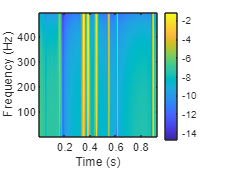

% Plot mel spectrogram
imagesc(T,F,log10(S+eps)); %log-scale and plot
axis xy; xlabel('Time (s)'); ylabel('Frequency (Hz)'); colorbar;

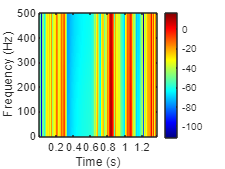

%For visualization purposes and optimization of parameters
window_size = round(0.003 * fs);      %3 ms window size
hop_size    = round(0.003/2 * fs);    %50% overlap

[SS,FF,TT]     = spectrogram(Diastole{1},window_size,hop_size,[],fs);

imagesc(TT,FF,20*log10(abs(SS)));
axis xy; % flip the y-axis
xlabel('Time (s)');
ylabel('Frequency (Hz)');
colormap(jet); % set the color map
colorbar; % show the color scale

%For Transfer Learning
counter = 0;
for i = 1:1
%Compute MelSpectrogram
M = melSpectrogram(S1{i}',fs,'WindowLength',round(win_length_sec*fs),...
    'OverlapLength',round((win_length_sec-hop_length_sec)*fs),...
    'FFTLength',nfft,'NumBands',n_mels,'FrequencyRange',[fmin,fmax]);

%Create 3 channels by duplicating it
Mel_3_channel = repmat(M, [1 1 3]);
%Resizing Mel-Spectrogram to [224 224]
Resized_Mel   = imresize(Mel_3_channel, [224 224]);
Mel_Spectro{1 + counter} = Resized_Mel;

M = melSpectrogram(Systole{i}',fs,'WindowLength',round(win_length_sec*fs),...
    'OverlapLength',round((win_length_sec-hop_length_sec)*fs),...
    'FFTLength',nfft,'NumBands',n_mels,'FrequencyRange',[fmin,fmax]);

Mel_3_channel = repmat(M, [1 1 3]);
Resized_Mel   = imresize(Mel_3_channel, [224 224]);
Mel_Spectro{2 + counter} = Resized_Mel;

M = melSpectrogram(S2{i}',fs,'WindowLength',round(win_length_sec*fs),...
    'OverlapLength',round((win_length_sec-hop_length_sec)*fs),...
    'FFTLength',nfft,'NumBands',n_mels,'FrequencyRange',[fmin,fmax]);

Mel_3_channel = repmat(M, [1 1 3]);
Resized_Mel   = imresize(Mel_3_channel, [224 224]);
Mel_Spectro{3 + counter} = Resized_Mel;

M = melSpectrogram(Diastole{i}',fs,'WindowLength',round(win_length_sec*fs),...
    'OverlapLength',round((win_length_sec-hop_length_sec)*fs),...
    'FFTLength',nfft,'NumBands',n_mels,'FrequencyRange',[fmin,fmax]);

Mel_3_channel = repmat(M, [1 1 3]);
Resized_Mel   = imresize(Mel_3_channel, [224 224]);
Mel_Spectro{4 + counter} = Resized_Mel;

counter = counter + 4;

end

%Turning Anomalies numeric values 0 1 to normal and abnormal for easier
%interpretation
Anomalies_S = cell(1, length(Anomalies));

% Logical indexing to replace 0 with 'normal' and 1 with 'abnormal'
Anomalies_S(Anomalies == 0) = {'normal'};
Anomalies_S(Anomalies == 1) = {'abnormal'};
Anomalies_C = categorical(Anomalies_S);
labels = Anomalies_C;

%Split the data set into three sets for training, validation, and testing
idx = splitlabels(labels,[0.8 0.1]);
traindata = Mel_Spectro(idx{1});
traindata = traindata'; %Transposing for the correct input dimension
trainlabels = labels(idx{1});
valdata = Mel_Spectro(idx{2});
valdata = valdata';
vallabels = labels(idx{2});
testdata = Mel_Spectro(idx{3});
testdata = testdata';
testlabels = labels(idx{3});

save('C:\Users\tpade\Desktop\Disertation\Code\ExtractedData\Mel_Train_Data.mat',"testdata","testlabels","traindata",...
     "trainlabels","valdata","vallabels","Mel_Spectro");